% This script filters out the aircrafts from the dataMasterList.mat that are
% needed for analysis basd on those in the RemovalDates matfile.
% It gives out a secondary master list containing only aircrafts whose generators 
% we want to analyse, with the flight data filtered thru to include only those whose dates are within the selected period.

% The output table has the following format:
% Removal Date | aircraft | Defects | faulty Generator | [type of fault] x 5 columns
%  | ShopFindings | NumFlightsb4Rem | NumFlightsOnRemDate |
% NumFlightsAftRem | Workability | data

% Each row of the data column contains a table of the following format
% data: date | num | filepath

clear

Conf=config;
PATH_TO_IDG_PROCESSED_DATA = Conf.PATH_TO_IDG_PROCESSED_DATA;
PATH_TO_IDG_MATFILES = Conf.PATH_TO_IDG_MATFILES;
PATH_TO_REM_DATES_MATFILE = Conf.PATH_TO_REM_DATES_MATFILE;
AIRCRAFTS = Conf.AIRCRAFTS;
SAMPLING_PERIOD = Conf.SAMPLING_PERIOD;

dataMasterList = load(fullfile(PATH_TO_IDG_MATFILES, "dataMasterList.mat"));
dataMasterList = dataMasterList.data;

% Obtain the removal dates table for reference
remDatesTbl = load(PATH_TO_REM_DATES_MATFILE);
remDatesTbl = remDatesTbl.RemovalDataandSFRfor15ComponentsS3;
remDatesTbl = remDatesTbl(remDatesTbl.DESCRIPTION == "IDG-INTEGRATED DRIVE GENERATOR",{'RemovalDate' 'AIRCRAFT' 'DEFECTS' 'ShopFindings'})

for row = 1:size(remDatesTbl,1)
    caseRemovalDate = remDatesTbl.RemovalDate(row);
    caseRemovalDate.Format = "dd-MM-uuuu";
    caseAircraft = remDatesTbl.AIRCRAFT(row);
    
    selectedAircraft = dataMasterList.Aircraft == string(caseAircraft);
    caseData = dataMasterList(selectedAircraft,{'NumFiles' 'data'});
    
    totalNumFlights = caseData.NumFiles;
    latestDate = caseRemovalDate + SAMPLING_PERIOD;
    earliestDate = caseRemovalDate - SAMPLING_PERIOD;
    
    withinSelectedPeriod = caseData.data{1}.date >= earliestDate & caseData.data{1}.date <= latestDate;
    remDatesTbl.data(row) = {caseData.data{1}(withinSelectedPeriod,:)};
    
    remDatesTbl.NumFlightsBeforeRemoval(row) = sum(caseData.data{1}.date < caseRemovalDate);
    remDatesTbl.NumFlightsOnRemovalDate(row) = sum(caseData.data{1}.date == caseRemovalDate);
    remDatesTbl.NumFlightsAfterRemoval(row) = sum(caseData.data{1}.date > caseRemovalDate);
    remDatesTbl.TotalNumFlights(row) = numel(caseData.data{1}.date);
    remDatesTbl.Workability(row) = logical(remDatesTbl.NumFlightsBeforeRemoval(row)*remDatesTbl.NumFlightsAfterRemoval(row));
    
    
    defect = remDatesTbl.DEFECTS(row);
    remDatesTbl.HighOilConsumption(row) = contains(defect,"consumption",'IgnoreCase',true);
    remDatesTbl.LowOilPressure(row) = contains(defect,["press" "pressure" "pr."],'IgnoreCase',true);
    remDatesTbl.GenFault(row) = contains(defect,"fault",'IgnoreCase',true);
    remDatesTbl.HighOilTemp(row) = contains(defect,["ovht" "high oil temp" "high oil temperature"],'IgnoreCase',true);
    remDatesTbl.DPIPopout(row) = contains(defect,"pop",'IgnoreCase',true);
    if contains(defect,"1")
        remDatesTbl.FaultyGen(row) = 1;
    elseif contains(defect,"2")
        remDatesTbl.FaultyGen(row) = 2;
    end
 end   
    
remDatesTbl=movevars(remDatesTbl,"Workability","After",numel(remDatesTbl.Properties.VariableNames))

% writetable(removevars(remDatesTbl,"data"),"CaseAccountingTableMetaData.xlsx")
% save("CaseAccountingTableData.mat",remDatesTbl(:,{'RemovalDate' 'AIRCRAFT' 'data'}))

workTbl = remDatesTbl(remDatesTbl.Workability==1,:)
for row = 1:size(workTbl,1)
    CATrow = workTbl(row,{'RemovalDate' 'AIRCRAFT' 'data'});
    aircraft = CATrow.AIRCRAFT;
    data = CATrow.data{1};
    for flight = 1:size(data,1)
        % Calculate numCols, Variable names, Flight Phase, Baro Alt, Calibrated Air Speed
        flightRow = data(flight,:);
        tbl = load(flightRow.filepath);
        varNames = tbl.tbl.Properties.VariableNames;
        FP = sum(contains(varNames,"FlightPhase",'IgnoreCase',true));
        BA = sum(contains(varNames,"BarometricAltitude",'IgnoreCase',true));
        CAS = sum(contains(varNames,"CalibratedAirSpeed",'IgnoreCase',true));
        ENG1N1 = sum(contains(varNames,"N1Eng1",'IgnoreCase',true));
        ENG1N2 = sum(contains(varNames,"N1Eng2",'IgnoreCase',true));
        ENG2N1 = sum(contains(varNames,"N2Eng1",'IgnoreCase',true));
        ENG2N2 = sum(contains(varNames,"N2Eng2",'IgnoreCase',true));


        data.FlightPhase(flight) = FP;
        data.BaroAltitude(flight) = BA;
        data.AirSpeed(flight) = CAS;
        data.EngineTurbine(flight) = ENG1N1 * ENG1N2 * ENG2N1 * ENG2N2;
    end
    workTbl.data(row) = {data};
    bothPhaseAndEng = logical(data.EngineTurbine) & logical(data.FlightPhase) & logical(data.BaroAltitude) & logical(data.AirSpeed);
    workTbl.b4RemDate(row) = sum(bothPhaseAndEng(data.date < CATrow.RemovalDate));
    workTbl.aftRemDate(row) = sum(bothPhaseAndEng(data.date > CATrow.RemovalDate));
    
end

0 flights b4 remdate

0 flight after remdate

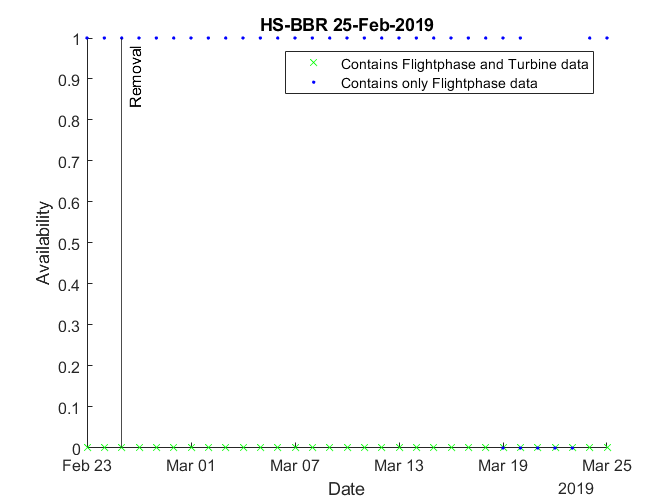

0 flights b4 remdate

0 flight after remdate

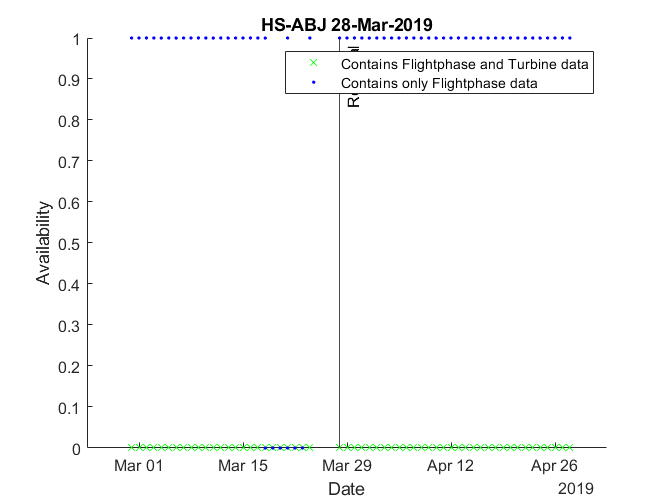

0 flights b4 remdate

0 flight after remdate

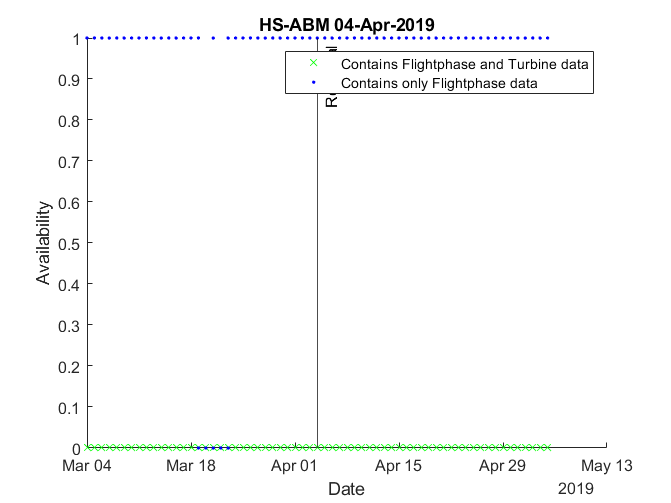

8 flights b4 remdate

0 flight after remdate

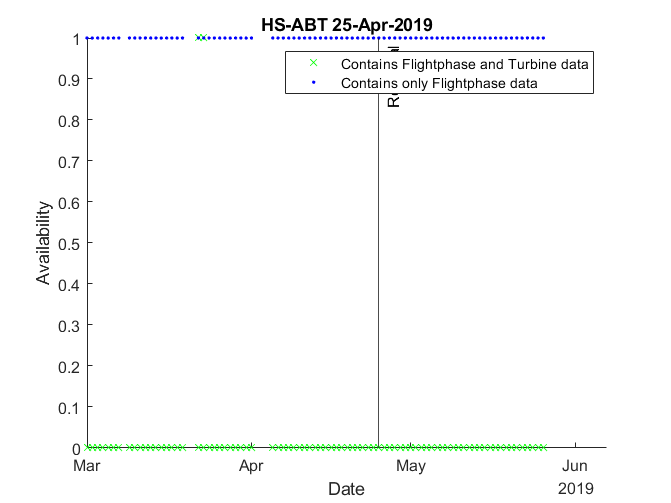

24 flights b4 remdate

526 flight after remdate

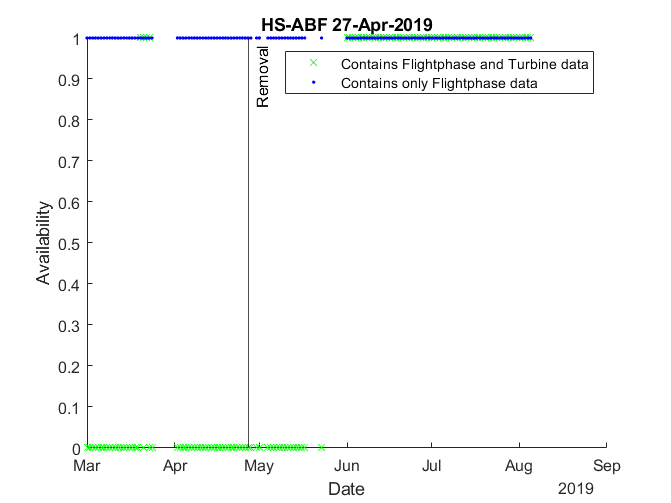

241 flights b4 remdate

0 flight after remdate

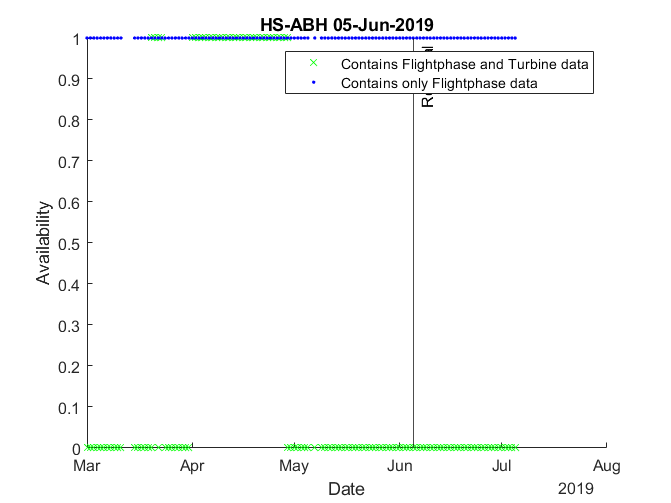

0 flights b4 remdate

0 flight after remdate

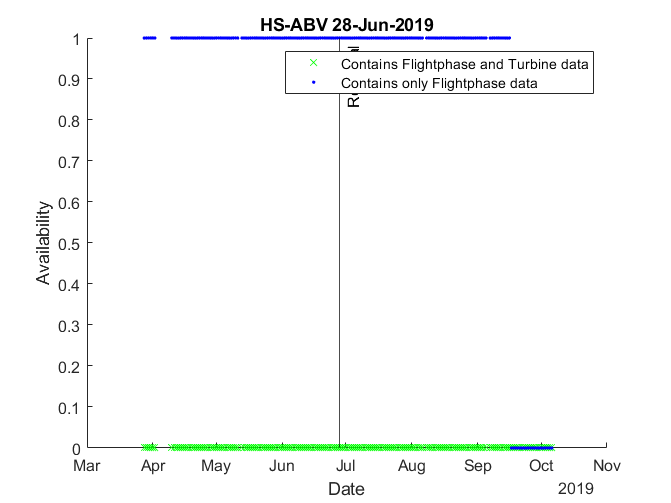

63 flights b4 remdate

0 flight after remdate

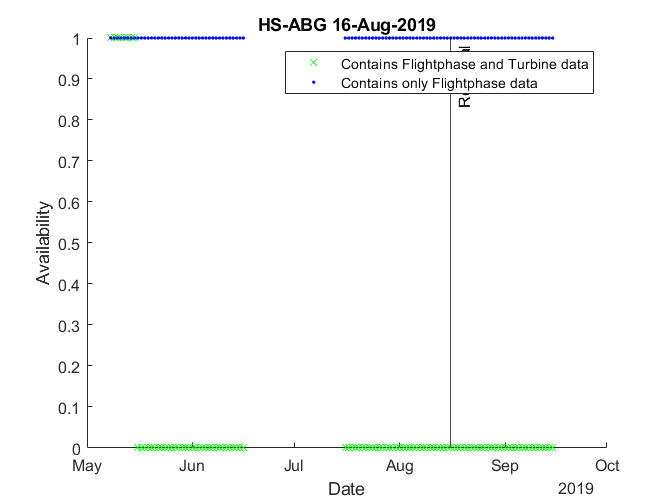

65 flights b4 remdate

0 flight after remdate

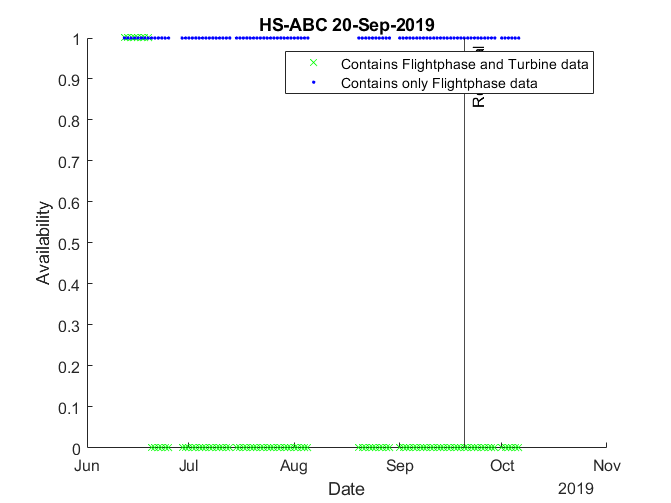

47 flights b4 remdate

88 flight after remdate

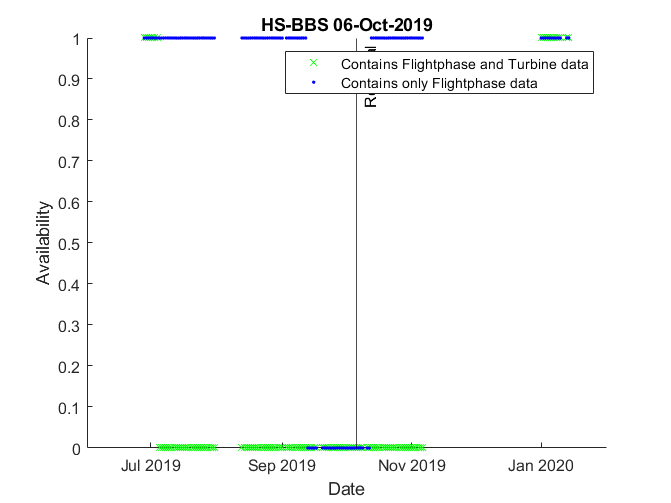

0 flights b4 remdate

147 flight after remdate

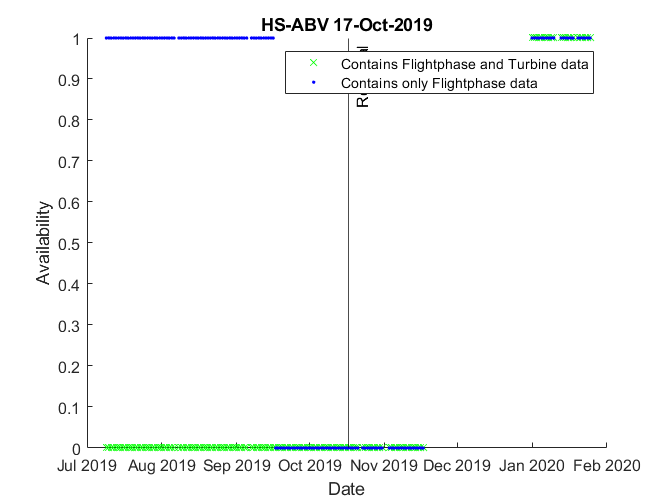

121 flights b4 remdate

146 flight after remdate

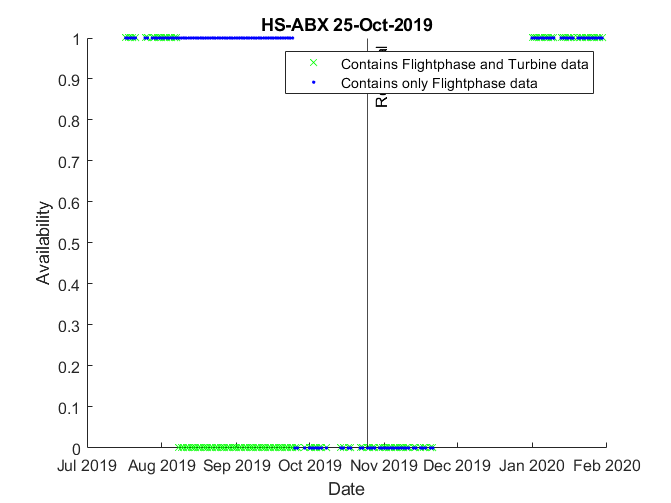

64 flights b4 remdate

434 flight after remdate

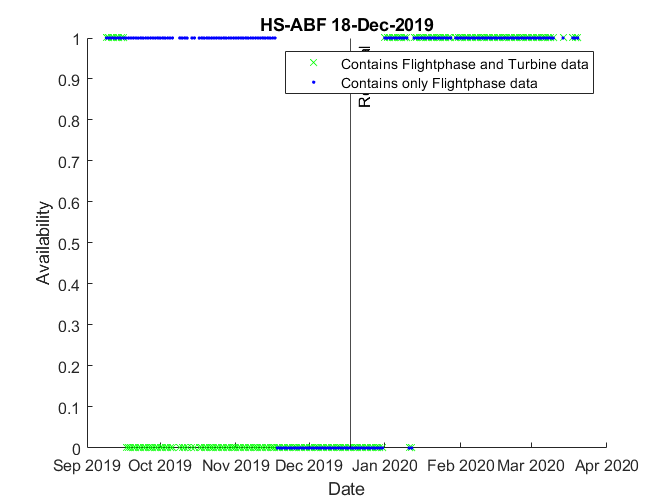

177 flights b4 remdate

446 flight after remdate

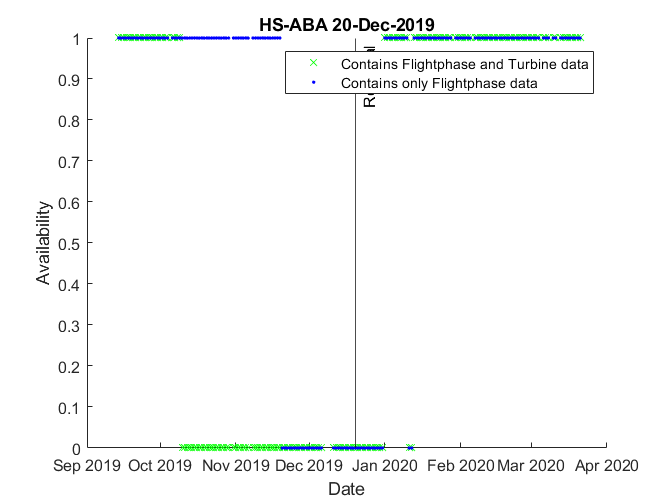

496 flights b4 remdate

316 flight after remdate

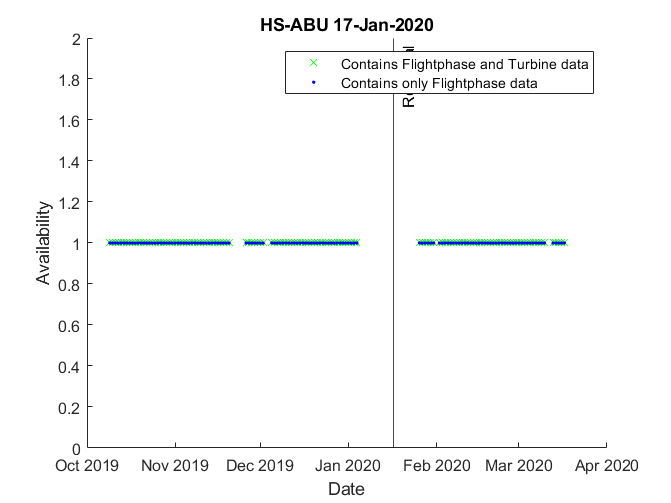

175 flights b4 remdate

172 flight after remdate

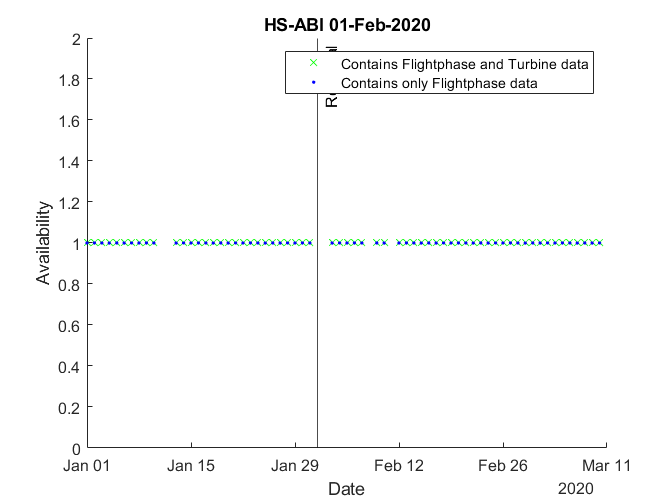

534 flights b4 remdate

183 flight after remdate

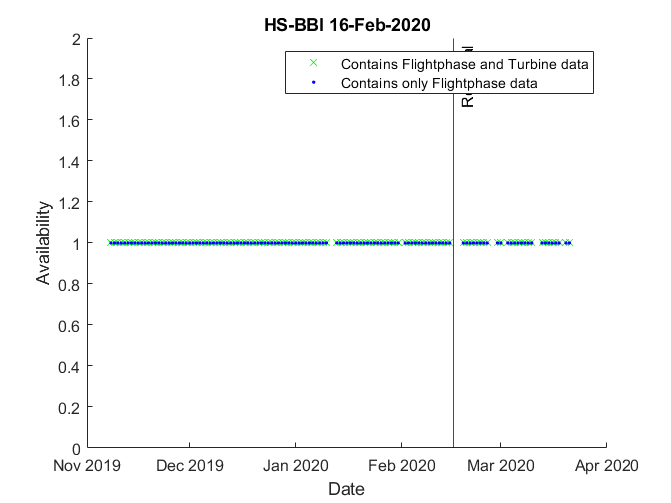

219 flights b4 remdate

160 flight after remdate

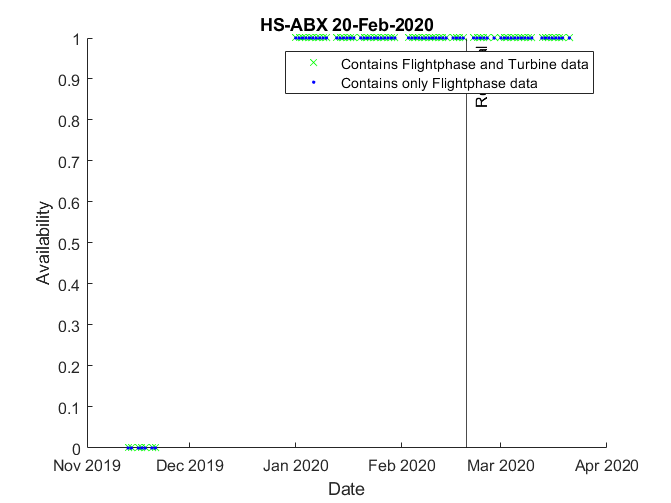

445 flights b4 remdate

80 flight after remdate

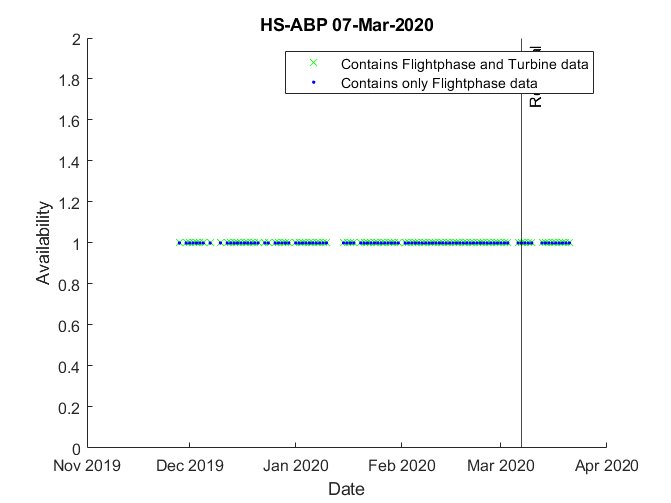

for row = 1:size(workTbl,1)
    data = workTbl.data(row);
    data = data{1};
    aircraft = workTbl.AIRCRAFT(row);
    caseRemDate = workTbl.RemovalDate(row);
    
    figure(row)
    hold on
    ylabel("Availability")
    xlabel("Date")
    title(string(aircraft) + " " + string(caseRemDate))
    scatter(data.date,logical(data.EngineTurbine) & logical(data.FlightPhase) & logical(data.BaroAltitude) & logical(data.AirSpeed),"green","x") % Contains both eng and flightphase
    scatter(data.date, logical(data.FlightPhase),"blue",".")% Contains only flightphase
    
    fprintf("%d flights b4 remdate",workTbl.b4RemDate(row))
    fprintf("%d flight after remdate",workTbl.aftRemDate(row))
    l=legend(["Contains Flightphase and Turbine data" "Contains only Flightphase data"]);
    l.AutoUpdate = 'off';
    xline(caseRemDate,"k-","Removal")
end